# Genetik Opimizasyon  Algoritması ile DC motor PID Parametre Tahmini

## DC Motor

DC motor, doğru akım ile çalışır. Elektrik akımı, motorun içindeki tellerden geçtiğinde manyetik bir alan oluşturur. Motorun içindeki sabit mıknatıslar bir manyetik alan sağlar. Bu alan, tellerden geçen akımın oluşturduğu manyetik alanla etkileşime girer.Bu iki manyetik alan birbirini iter ve çeker. Bu kuvvetler, motorun içindeki rotoru hareket ettirir. Rotorun sürekli dönmesi için, akımın yönü düzenli olarak değiştirilir. Bu işi motorun içindeki **komütatör** ve **fırçalar** yapar.

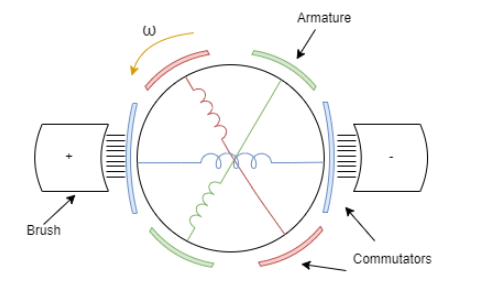

**Elektriksel Denklem**

Fırçalı DC Motorlar elektriksel ve tork karakteristiklerinin gösterimi aşağıdaki denklemlerde açıklanmıştır.

#  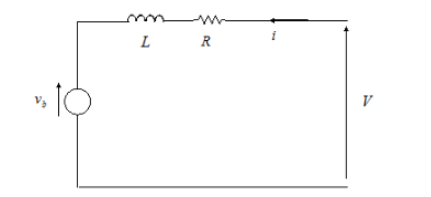

$V_{\left(t\right)}$ = L$\frac{\mathrm{dt}}{\mathrm{di}}+{\mathrm{Ri}}_{\left(t\right)} +{\mathrm{eb}}_{\left(t\right)}$

Burada:

$V_{\left(t\right)}$: Motor uçlarına uygulanan gerilim (V),

$L$: Motor endüktansı (H),

$R$: Motor direnci (Ω),

$i_{\left(t\right)}$: Motor akımı (A),

$e_b \left(t\right)$: Geri elektromotor kuvvet (EMF) (V).

**Mekanik Denklem**

Motorun mekanik kısmı Newton'un ikinci yasasıyla modellenir:


$$\begin{array}{l}
T_{\left(t\right)} =J\;\frac{d\omega_{\left(t\right)} }{\mathrm{dt}}+b\omega_{\left(t\right)} \\

\end{array}$$


$T_{\left(t\right)}$: Motor tarafından üretilen tork ($\mathrm{Nm}$),

$j$: Rotorun atalet momenti ($\mathrm{kg}\ldotp m^2$),

$b$: Viskoz sürtünme katsayısı ($\;\frac{\mathrm{Nm}\ldotp s}{\mathrm{rad}}$),

$\omega_{\left(t\right)}$: Rotorun açısal hızı ($\frac{\mathrm{rad}}{s}$).

Motor tarafından üretilen tork, akımla ilişkilidir:


$$T_{\left(t\right)} =K_t i_{\left(t\right)}$$


$K_t$ = Motor tork sabiti $\frac{\mathrm{Nm}}{A}$

**DC Motorun Transfer Fonksiyonu**

**Elektriksel ve Mekanik Denklemlerin Laplace Dönüşümü**

**Elektriksel Denklem:**


$$V_{\left(s\right)} =L_s I_{\left(s\right)} +{\mathrm{RI}}_{\left(s\right)} +K_e \omega_{\left(s\right)}$$


**Mekanik Denklem**


$$\;K_t \;I_{\left(s\right)} =\mathrm{Js}\;\omega_{\left(s\right)} +b\omega_{\left(s\right)}$$


**Akım ve Açısal Hız Arasındaki İlişki**

Elektriksel denklemi $I_{\left(s\right)} \;\;$cinsinden çözmek için 


$$I_{\left(s\right)} =\frac{V_{\left(s\right)} -k_e \Omega_{\left(s\right)} }{L_s +R}$$


Akımı Mekanik denklemde yerine yazarsak 


$$\begin{array}{l}
\omega_{\left(s\right)} \left(\mathrm{Js}+b\right)=\frac{\mathrm{Kt}}{L_s +R}\;\left(V_{\left(s\right)} -K_e \Omega_{\left(s\right)} \right)\\
\\
\omega_{\left(s\right)} \left\lbrack \left(J_s +b\right)\left(L_s +R\right)+K_e K_t \right\rbrack =K_t V_{\left(s\right)} \\
\\
\frac{\omega_{\left(s\right)} }{V_{\left(s\right)} }=\frac{K_t }{\left(J_s +b\right)\left(L_s R\right)+K_e K_t }\\

\end{array}$$


$J$ ve$b$ mekanik kısmı temsil eder.

$L$ ve $R$ elektriksel kısmı temsil eder.

$K$ geri EMF sabiti ve tork sabiti arasındaki orantıyı ifade eder ($K_t =K_e$�)

**Transfer Fonksiyonunun Yorumlanması**


$$G_{\left(s\right)} =\frac{\omega_{\left(s\right)} }{V_{\left(s\right)} }=\frac{K_t }{\left(J_s +b\right)\left(L_s R\right)+K_e K_t }$$


**Pay:** Motor sabiti $K_t$�, motorun gerilime yanıt olarak tork üretme kapasitesini temsil eder.

**Payda:** Motorun dinamik davranışını belirler. $J_s$, b, $L$ $R$ ve $K$ motorun hız ve tork özelliklerini şekillendirir.

**Step Girişin Laplace Dönüşümü**

Birim bir step giriş


$$V_{\left(t\right)} =1\;\;\;\;\;t=0$$


Bu girişin Laplace dönüşümü:


$$V_{\left(s\right)} =\frac{1}{s}$$


Sistemin çıkışını bulmak için transfer fonksiyonuna $V_{\left(s\right)}$ step girişini uygularız:


$$w_{\left(s\right)} =G_{\left(s\right)} V_{\left(s\right)} =\frac{K_t }{\left(J_s +b\right)\left(L_s R\right)+K_e K_t }\;\ldotp \frac{1}{s}$$


**Sistemin Açısal Hız Çıkışı **


$$w_{\left(s\right)} =G_{\left(s\right)} V_{\left(s\right)} =\frac{K_t }{s\left\lbrack \left(J_s +b\right)\left(L_s R\right)+K_e K_t \right\rbrack }\;$$



$$w_{\left(s\right)} =G_{\left(s\right)} V_{\left(s\right)} =\frac{K_t }{s\left({\mathrm{JLs}}^2 +\left(\mathrm{JR}+\mathrm{Lb}\right)s\right)+\left(\mathrm{bR}+K_e K_t \right)}\;$$


Bu, sistemin 2. dereceden bir diferansiyel denklemle karakterize edildiğini gösterir. Denklemin katsayıları aşağıdakigibidir.

$a_2 =\mathrm{JL}$: Sistemin atalet momenti ve endüktansına bağlıdır.

$a_1 =\mathrm{JR}+\mathrm{Lb}$ Direnç ve viskoz sürtünmeye bağlıdır.

$a_0 =\mathrm{bR}+K_e K_t$: Geri EMF ve motor tork sabiti ile ilişkilidir.

Transfer fonksiyonu şu şekilde yazılabilir:


$$w_{\left(s\right)} =\frac{K_t }{{a_2 s}^3 +{a_1 s}^2 +a_0 s}$$


**Step Tepkisinin Zaman Domeninde Analizi**

Polinomun Kökleri (Kutup Analizi)


$${a_2 s}^3 +{a_1 s}^2 +a_0 s$$


Kökler $s_1 ,s_2$� ile ifade edilir:


$$s_{1,2} =\frac{-a_1 \pm \sqrt{a_1^2 -4a_2 a_0 }}{2a_2 }$$


Laplace dönüşüm teorisine göre, 2. dereceden bir sistemin step yanıtı şu şekilde ifade edilir:


$$w_{\left(t\right)} =K\left(1-e^{-s_1 t} \cos \left(w_d t\right)+\phi \right)\;$$


K: Sistem kazancı (DC kazanç),

$s_1$�: Sistem damping faktörü,

$\omega_d$: Sönümlü doğal frekans.

DC kazanç, s→0  limitinde transfer fonksiyonu ile belirlenir:


$$G_{\left(0\right)} =\lim_{s\rightharpoonup 0} \left(G_{\left(s\right)} \right)=\frac{K_t }{\mathrm{bR}+K_e K_t }$$


**Neden Step:**

- **Başlangıç Değeri**: Motor, momentin ataletle ilişkisine bağlı olarak sıfır hızdan başlar.

- **Yerleşme Süresi**: Motorun kararlı duruma ulaşma süresi.

- **Overshoot**: Motorun geçici olarak kararlı durum değerini aşması.

Yerleşme Zamanı (Settling Time)

**Tanım**

Yerleşme zamanı, sistemin geçici rejimden kararlı duruma geçişi için geçen süredir. Genellikle, sistemin çıkışının nihai değerinin belirli bir hata bandı (%2 veya %5) içinde kalması için geçen süre olarak tanımlanır.

**Matematiksel Tanım**

Yerleşme zamanı $t_s$�, aşağıdaki şekilde ifade edilir:


$$t_s =\frac{-\ln \left(\epsilon \right)}{\zeta \omega_n }$$


$\epsilon$: Hata bandı (örneğin, %2 için ϵ=0.02\epsilon = 0.02ϵ=0.02),

$\zeta$: Sönüm oranı (damping ratio),

$\omega_n$�: Doğal frekans (natural frequency).

Sistemin Yerleşme Zamanı


$$G_{\left(s\right)} =\frac{K}{\tau s^2 +2\zeta \omega_n s+w_n^2 }$$


Bu denklemden $\zeta$ ve $\omega_n$� değerleri şu şekilde hesaplanır:

ζ (sönüm oranı), karakteristik denklemin köklerinden türetilir.

$\omega_n$(doğal frekans), karakteristik denklemin katsayılarından hesaplanır:

Sistem transfer fonksiyonunda $\tau ,\zeta ,\omega_n$� gibi parametreler yerine konularak $t_s$� bulunur.

**Aşım Miktarı (Overshoot)**

**Tanım**

Aşım miktarı, sistemin geçici durum sırasında kararlı durum değerini ne kadar aştığını ifade eder. Genellikle yüzdelik olarak belirtilir.

**Matematiksel Tanım**

Aşım miktarı $M_p$�, aşağıdaki şekilde ifade edilir:


$$M_p =e^{-\;\frac{\zeta \pi }{\sqrt{1-\zeta^2 }}}$$


ζ: Sönüm oranı (damping ratio).

** Sistemin Aşım Miktarı**

Sistemin aşım miktarı, transfer fonksiyonunun karakteristik köklerinden hesaplanan $\zeta$ değeri kullanılarak bulunur.

**Genetik Algoritmanın Tanımı**

Genetik algoritma (GA), biyolojik evrimi taklit ederek karmaşık problemlerin çözümünde kullanılan, popülasyon temelli bir optimizasyon yöntemidir. Bu algoritma, doğal seçilim, çaprazlama (crossover) ve mutasyon gibi mekanizmaları kullanarak en iyi çözüme iteratif bir şekilde yaklaşır.

Genetik algoritma, aşağıdaki adımları izleyerek PID kontrolcüsünün ${K_p ,K_i \;\mathrm{ve}\;K}_d$� katsayılarını optimize eder. Simple Genetik Optimizasyon algoritmasının akış diyagramı aşağıda paylaşılmıştır.

  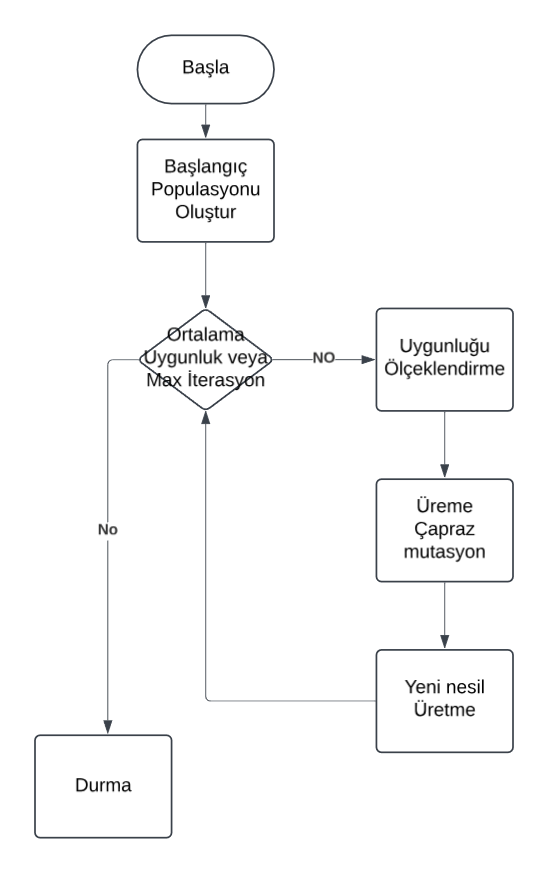

İşlem adımları Şu şekildedir.

**Başlangıç Popülasyonu**

Algoritma, rastgele PID parametrelerinden oluşan bir başlangıç popülasyonu oluşturur:


$$\mathrm{population}=\left\lbrace {\left(K_p K_i K_d \right)}_1 ,\ldotp \ldotp \ldotp ,{\left(K_p K_i K_d \right)}_N \right\rbrace$$


**Popülasyon Büyüklüğü** $N=20$:olrak belirlenmiştir.

Her birey $K_p K_i K_d$ değerlerini temsil eder.

BElirlenen aralıklarda rastgele değerler oluşturulur.


$$\begin{array}{l}
K_p \;\in \left\lbrack 0,100\right\rbrack \\
K_i \;\in \left\lbrack 0,100\right\rbrack \\
K_d \;\in \left\lbrack 0,20\right\rbrack 
\end{array}$$


**Fitness Değerlendirmesi**

Her bireyin performansı, bir maliyet fonksiyonu$J$kullanılarak değerlendirilir. Maliyet fonksiyonu, step yanıtındaki yerleşme zamanı $t_s$ ve aşım miktarını $M_p$ optimize etmeyi hedefler:


$$J=|\;t_s -{t_s }^{\mathrm{hedef}} |+\left\lbrace \begin{array}{ll}
0, & M_p \le {M_p }^{\mathrm{limit}} \\
100 & M_p >{M_p }^{\mathrm{limit}} 
\end{array}\right.$$
 

- **Yerleşme Zamanı (**$t_s$**�****)**: Sistem kararlı duruma ulaşmalıdır.

- **Aşım Miktarı (**$M_p$**�****)**: Belirlenen limitlerin altında tutulmalıdır.

- Hedef yerleşme zamanı: ${t_s }^{\mathrm{hedef}}$=0.2 saniye.

- Maksimum aşım: $M_p =%20$ 

**Seçilim (Selection)**

Popülasyondan bireyler, fitness değerlerine bağlı olarak seçilir. Daha düşük maliyet değerine sahip bireylerin seçilme olasılığı daha yüksektir.

**Çaprazlama (Crossover)**

Seçilen bireyler arasında genetik materyalin değişimi gerçekleştirilir:

- **Çaprazlama Oranı**: 0.80 (çiftlerin %80’i çaprazlanır).

- Arithmetic crossover yöntemi kullanılır:


$$\begin{array}{l}
{\mathrm{child}}_1 =a\ldotp {\mathrm{parent}}_1 +\left(1-a\right){\mathrm{parent}}_2 \\
{\mathrm{child}}_2 =\left(1-a\right){\mathrm{parent}}_1 +a{\ldotp \mathrm{parent}}_2 
\end{array}$$


Burada rastgele bir ağırlık katsayısıdır.


$$\left(0\le \mathrm{𝛼}\le 10\le \alpha \le 1\right)\ldotp$$


**Mutasyon (Mutation)**

Genetik çeşitliliği artırmak ve yerel minimumdan kaçınmak için bireylerin bazı genleri rastgele değiştirilir.

**Mutasyon Oranı**: 0.20 (bireylerin %20’sinde değişiklik yapılır).

Rastgele bir PID parametresi ($K_p K_i K_d$�) seçilir ve rastgele bir değere atanır.

**Yeni Popülasyonun Oluşturulması**

Yeni bireyler, çaprazlama ve mutasyon işlemleriyle oluşturulur ve bir sonraki jenerasyonun başlangıç popülasyonu olur.

**Durma Kriteri**

Algoritma, belirli bir jenerasyon sayısından (20) sonra veya en iyi çözümün maliyet fonksiyonunda yeterince küçük bir iyileşme olduğunda durur.

**Kodun Açıklaması**

DC motorun dinamik davranışı aşağıdaki parametrelerle modellenmiştir:

- $J$**: Atalet momenti** ($\mathrm{kg}\ldotp m^2$) - 0.01

- $b$**: Sürtünme katsayısı** ($\frac{\mathrm{Nm}\ldotp s}{\mathrm{rad}}$) - 0.1

- $K$**: Motor sabiti** ($\frac{\mathrm{Nm}}{A}$) - 0.05

- $R$**: Direnç** (Ω) - 1

- $L$**: Endüktans** (H) - 0.5

Motor Parametreleri aşağıdaki gibi oluşturulmuştur.

J = 0.01;  % Atalet momenti
b = 0.1;   % Sürtünme katsayısı
K = 0.05;  % Motor sabiti
R = 1;     % Direnç
L = 0.5;   % Endüktans


Motorun matematiksel modeli transfer fonksiyonuyla ifade edilmiştir:

$G_{\left(s\right)} =\frac{\omega_{\left(s\right)} }{V_{\left(s\right)} }=\frac{K_t }{\left(J_s +b\right)\left(L_s R\right)+K_e K_t }$�

Bu ifade, MATLAB'de şu şekilde tanımlanmıştır:

s = tf('s');
G = K / ((J*s + b)*(L*s + R) + K^2);

**Optimizasyon Probleminin Tanımı**

**Amaç**

PID kontrolcüsünün parametrelerini ($K_p ,K_i ,K_d$�) optimize ederek:

**Yerleşme Zamanı (**$t_s$**�****)**: 0.5 saniye hedeflenmiştir.

**Aşım Miktarı (**$M_p$**�****)**: Maksimum %20 aşımı sınırlandırmak

target_settling_time = 0.5; % Hedef yerleşme süresi (saniye)
overshoot_limit = 20;       % Maksimum aşım (%)

**Genetik Algoritma Parametrelerinin Belirlenmesi**

pop_size = 50;            % Popülasyon büyüklüğü
max_gen = 50;             % Maksimum jenerasyon
mutation_rate = 0.2;      % Mutasyon oranı
crossover_rate = 0.8;     % Çaprazlama oranı
range_Kp = [0, 100];      % Kp aralığı
range_Ki = [0, 50];       % Ki aralığı
range_Kd = [0, 20];       % Kd aralığı

**pop_size**: Popülasyondaki birey sayısı.

**max_gen**: Algoritmanın çalışacağı maksimum jenerasyon sayısı.

**mutation_rate**: Mutasyon işleminin gerçekleşme olasılığı.

**crossover_rate**: Çaprazlama işleminin gerçekleşme olasılığı.

**range_Kp, range_Ki, range_Kd**: PID katsayıları ($K_p ,K_i ,K_d$�) için tanımlanan minimum ve maksimum değer aralıkları.

**Rastgele Popülasyonun Oluşturulması**

population = [rand(pop_size, 1) * diff(range_Kp) + range_Kp(1), ...
              rand(pop_size, 1) * diff(range_Ki) + range_Ki(1), ...
              rand(pop_size, 1) * diff(range_Kd) + range_Kd(1)];

Her birey rastgele oluşturulan $K_p ,K_i ,K_d$�� parametrelerinden oluşur.

**rand(pop_size, 1)**: Popülasyondaki her birey için rastgele değerler oluşturur.

**diff(range)**: Katsayı aralıklarının genişliğini hesapla

**Başlangıç Değerlerinin Tanımlanması**

best_cost = Inf;
best_params = [];

**best_cost**: Şu ana kadar bulunan en düşük maliyet değeri. Başlangıçta sonsuz (Inf) olarak ayarlanır.

**best_params**: En iyi maliyet değerine sahip bireyin PID katsayıları.

**Renk Paleti Oluşturma**

colors = lines(max_gen);

**Optimizasyon Döngüsü**

for gen = 1:max_gen

 **gen**: Jenerasyon sayacıdır. Genetik algoritma, belirlenen maksimum jenerasyon (max_gen) kadar çalışır.

**Fitness Değerlendirmesi**

    for i = 1:pop_size
    Kp = population(i, 1);
    Ki = population(i, 2);
    Kd = population(i, 3);
    fitness(i) = calculate_cost_ga_pid(Kp, Ki, Kd, G, target_settling_time, overshoot_limit);

**Kp, Ki, Kd**: Mevcut bireyin PID katsayıları.

**calculate_cost_ga_pid**: Bireyin uygunluk değerini (fitness) hesaplar. Bu değer, step yanıtındaki yerleşme süresi ve aşım miktarına dayalıdır.

**Step Yanıtının Kaydedilmesi**

C = Kp + Ki/s + Kd*s;
T = feedback(C*G, 1);
[y, t] = step(T);
all_responses{gen, i} = struct('time', t, 'response', y);

**C**: PID kontrolcüsünün transfer fonksiyonu.

**T**: Kapalı döngü transfer fonksiyonu.

**step(T)**: Sistemin step yanıtını simüle eder.

**all_responses**: Tüm jenerasyon ve bireylerin yanıtlarını saklar.

**En İyi Çözümün Kaydedilmesi**

if current_best_cost < best_cost
    best_cost = current_best_cost;
    best_params = population(best_idx, :);
end

**best_cost**: En iyi maliyet değeri güncellenir.

**best_params**: En iyi bireyin PID katsayıları güncellenir.

**Çaprazlama ve Mutasyon**

alpha = rand;
child1 = alpha * parent1 + (1 - alpha) * parent2;
child2 = (1 - alpha) * parent1 + alpha * parent2;

**Çaprazlama**: İki ebeveynin genetik bilgileri karıştırılarak çocuk bireyler oluşturulur.

if rand < mutation_rate
    new_population(i, 1) = rand * diff(range_Kp) + range_Kp(1);
end

**Mutasyon**: Rastgele bir gen değiştirilerek çeşitlilik sağlanır.

**Step Yanıtlarının Görselleştirilmesi**

for gen = 1:max_gen
    plot(data.time, data.response, 'Color', colors(gen, :));
end

Jenerasyonlardaki tüm step yanıtlarını çizer.

**Optimize Edilmiş Yanıt ve Açık Döngü Motor Yanıtı**

plot(t_opt, y_opt, 'b', 'DisplayName', 'Optimize Edilmiş PID Step Yanıtı');
plot(t_motor, y_motor, 'r--', 'DisplayName', 'Motor Step Yanıtı (Açık Döngü)');

Optimize edilen ve açık döngü step yanıtları aynı grafikte gösterilir.

**Optimize Edilmiş Yanıt ve Açık Döngü Motor Yanıtı Çizimi**

figure;
hold on;
% Optimize edilmiş kontrolcünün yanıtı
C_opt = best_params(1) + best_params(2)/s + best_params(3)*s;
T_opt = feedback(C_opt*G, 1);
[y_opt, t_opt] = step(T_opt);

**C_opt**: Genetik algoritma ile optimize edilmiş PID katsayıları $K_p {,K}_i {,K}_d$ ile oluşturulan PID kontrolcüsü transfer fonksiyonu.

**T_opt**: Optimize edilmiş PID kontrolcüsü ile elde edilen kapalı döngü transfer fonksiyonu.

**step(T_opt)**: Optimize edilmiş PID kontrolcüsünün kapalı döngüdeki step yanıtını hesaplar ve $y_{\mathrm{opt}}$� ile zamana bağlı olarak $t_{\mathrm{opt}}$� değerlerini döndürür.

**Maliyet Fonksiyonu**

Her bireyin başarısı bir maliyet fonksiyonuyla değerlendirilir:


$$J=|\;t_s -{t_s }^{\mathrm{hedef}} |+\left\lbrace \begin{array}{ll}
0, & M_p \le {M_p }^{\mathrm{limit}} \\
100 & M_p >{M_p }^{\mathrm{limit}} 
\end{array}\right.$$
 

${t_s }^{\mathrm{hedef}}$ = 0.5 saniye

${M_p }^{\mathrm{limit}}$ = 20%

MATLAB'de bu fonksiyon şu şekilde tanımlanmıştır:

function J = calculate_cost_ga_pid(Kp, Ki, Kd, G, target_settling_time, overshoot_limit)
    % PID kontrolcüyü oluştur
    C = Kp + Ki/s + Kd*s;
    T = feedback(C*G, 1);
    info = stepinfo(T);

    % Maliyet hesaplama
    settling_time = info.SettlingTime;
    overshoot = info.Overshoot;
    J = abs(settling_time - target_settling_time) + (overshoot > overshoot_limit) * 100;
end

**Genetik Algoritmanın Uygulanması**

**Başlangıç Popülasyonu**

Popülasyon, rastgele oluşturulan bireylerden ($K_p ,K_i ,K_d$�) oluşur:


$$\begin{array}{l}
K_p \;\in \left\lbrack 0,100\right\rbrack \\
K_i \;\in \left\lbrack 0,100\right\rbrack \\
K_d \;\in \left\lbrack 0,20\right\rbrack 
\end{array}$$


Başlangıç popülasyonu şu şekilde tanımlanmıştır:

population = [rand(pop_size, 1) * diff(range_Kp) + range_Kp(1), ...
              rand(pop_size, 1) * diff(range_Ki) + range_Ki(1), ...
              rand(pop_size, 1) * diff(range_Kd) + range_Kd(1)];

**Fitness Değerlendirmesi**

Her birey için PID kontrolcüsü oluşturulur ve motorun kapalı döngü step yanıtı analiz edilerek fitness değeri hesaplanır:

for i = 1:pop_size
    Kp = population(i, 1);
    Ki = population(i, 2);
    Kd = population(i, 3);
    fitness(i) = calculate_cost_ga_pid(Kp, Ki, Kd, G, target_settling_time, overshoot_limit);
end

**Çaprazlama (Crossover)**

Çaprazlama işlemi, iki ebeveynin genetik materyallerini karıştırarak yeni bireyler oluşturur:

alpha = rand;
child1 = alpha * parent1 + (1 - alpha) * parent2;
child2 = (1 - alpha) * parent1 + alpha * parent2;

Function definitions in a script must appear at the end of the file.
Move all statements after the "calculate_cost_ga_pid" function definition to before the first local function definition.

 **Mutasyon (Mutation)**

Mutasyon işlemi, bireylerin genetik çeşitliliğini artırır:

if rand < mutation_rate
    mut_gene = randi(3); % Rastgele gen seçimi
    if mut_gene == 1
        new_population(i, 1) = rand * diff(range_Kp) + range_Kp(1);
    elseif mut_gene == 2
        new_population(i, 2) = rand * diff(range_Ki) + range_Ki(1);
    else
        new_population(i, 3) = rand * diff(range_Kd) + range_Kd(1);
    end
end

**Durma Kriteri**

if gen == max_gen
    break;
end

**Optimizasyon Sonuçlarının Görselleştirilmesi**

**Jenerasyonların Step Yanıtları**

Her jenerasyondaki bireylerin step yanıtları renkli olarak görselleştirilmiştir:

for gen = 1:max_gen
    for i = 1:pop_size
        data = all_responses{gen, i};
        plot(data.time, data.response, 'Color', colors(gen, :));
    end
end

**Optimize Edilmiş PID Kontrolcünün Step Yanıtı**

Algoritma sonucunda bulunan en iyi birey ile motorun step yanıtı çizdirilir:

T_opt = feedback(C_opt*G, 1);
[y_opt, t_opt] = step(T_opt);
plot(t_opt, y_opt, 'b', 'LineWidth', 2, 'DisplayName', 'Optimize Edilmiş PID Step Yanıtı');

**Motorun Açık Döngü Yanıtı**

Açık döngü yanıtı, optimize edilmiş kontrolcünün yanıtı ile karşılaştırılır:

[y_motor, t_motor] = step(G);
plot(t_motor, y_motor, 'r--', 'LineWidth', 2, 'DisplayName', 'Motor Step Yanıtı (Açık Döngü)');